% audionäytteiden tallennukseen käytetty koodi

Fs = 44100; 
T = 2;
% tiedostopolku nauhoitusten tallentamista varten
folder = 'C:\Users\onnib.000\OneDrive\Documents\Aalto\ELEC\äänen- ja puheenkäsittely\projekti\nauhoitukset';

% äänitys
recorder = audiorecorder(Fs, 16, 1); % tässä bittisyvyys 16 ja 1 kanava
disp('Start')

Start


recordblocking(recorder, T);
disp('End');

End


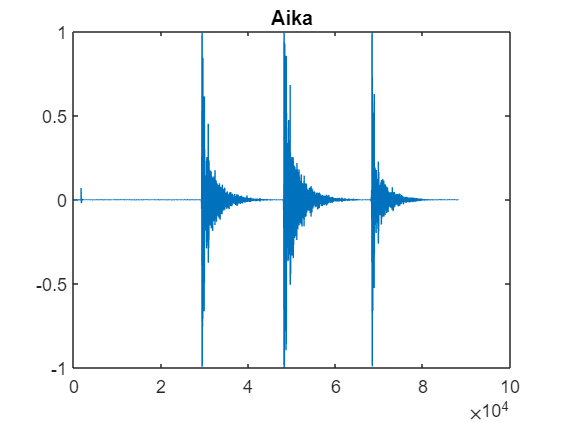


% toisto
play(recorder);

% tallennus
sitename = 'testi_';
y = getaudiodata(recorder);
filename = fullfile(folder, [sitename, char(datetime('now','Format','dd-MMM-yyyy_HH_mm_ss_SSS')), '.wav']);
audiowrite(filename, y, Fs);

% plottaukset, tosin aika turha sellainen
plot(y);
title('Aika');

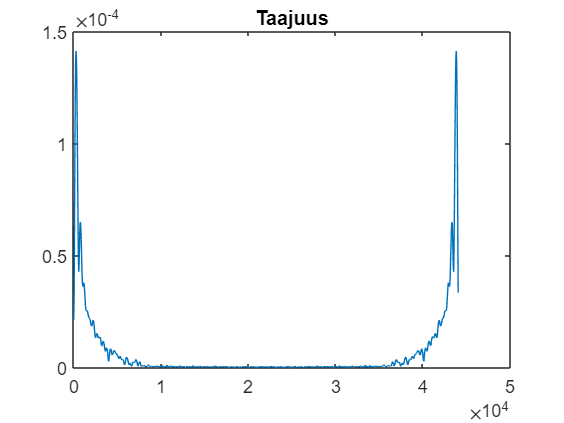

y_windowed = y.* hann(length(y));
Y = fft(y_windowed, 1024);
f = (0:length(Y)-1)*Fs/length(Y);
plot(f, abs(Y));
title('Taajuus');